# **ONE HUNDRED PHYSICS VISUALIZATIONS USING MATLAB    |    Dan Green**

**GROUP B:**

**MUHAMMAD NIZAR BIN ABD HALIM (207508)**

**VICTORIA LEONG KAI XIN (209034)**

**NURAINI BINTI MANSOR (209048)**

**LAAVEENA SYAM (203148)**

## **CHAPTER 5 : GASES AND FLUID FLOW**

## **5.4    Fermi-Dirac and Bose-Einstein Distributions**

Quantum mechanics implies that non-interacting particles will have effects due to their spin and statistics obeyed by fermions and bosons. For bosons, there can be any number of boson particles occupying a given quantum state; for fermions, the Fermi Exclusion Principle requires a limitation of at most two particles for spin 1/2, in a particular spatial quantum state. 

At low temperature, bosons will tend to accumulate in the lowest quantum state, while fermions will populate all states up to a maximum energy in pairs. 

The functions, $f$, are the mean occupation number of a quantum state of energy, $E$, approximated as a continuous variable, since the spacing between quantized energy levels is small and un-normalized here in the three cases of energy distribution models as explained in below sections.

## **Maxwell-Boltzmann Distribution (Boltzmann)**

The Maxwell-Boltzmann distribution describes the statistical distribution of speeds or energies of particles in a classical gas. It's applicable when the particles are distinguishable and non-interacting. The probability density function is given by:


$$f_{\textrm{MB}} \left(E\right)=e^{-\frac{E}{\textrm{kT}}}$$


where:

$f_{\textrm{MB}} \left(E\right)$ is the probability density function,

$E$ is the energy of a particle,

$k$ is the Boltzmann constant,

$T$ is the temperature.

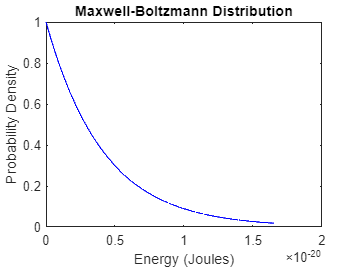

% Maxwell-Boltzmann Distribution
clear all;
T = 300; % Temperature in Kelvin
k = 1.38e-23; % Boltzmann constant

% Energy range
E = linspace(0, 4 * k * T, 1000);

% Maxwell-Boltzmann distribution function
f_Boltzmann = exp(-E / (k * T));

% Plotting
figure;
plot(E, f_Boltzmann, '-b');
xlabel('Energy (Joules)');
ylabel('Probability Density');
title('Maxwell-Boltzmann Distribution');

## **Bose-Einstein Distribution (BE)**

The Bose-Einstein distribution describes the distribution of identical bosons, which are particles with integer spin, such as photons or helium-4 atoms. It is characterized by the fact that multiple particles can occupy the same quantum state. The probability density function is given by:


$$f_{\textrm{BE}} \left(E\right)=\frac{1}{e^{-\frac{E}{\textrm{kT}}} -1}$$


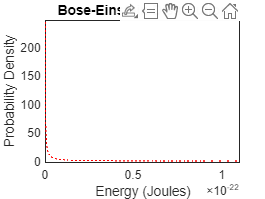

% Bose-Einstein Distribution
clear all;
T = 2; % Temperature in Kelvin
k = 1.38e-23; % Boltzmann constant

% Energy range
E = linspace(0, 4 * k * T, 1000);

% Bose-Einstein distribution function
f_BoseEinstein = 1 ./ (exp(E ./ (k * T)) - 1);

% Plotting
figure;
plot(E, f_BoseEinstein, ':r');
xlabel('Energy (Joules)');
ylabel('Probability Density');
title('Bose-Einstein Distribution');

## Fermi-Dirac Distribution (FD)

The Fermi-Dirac distribution describes the distribution of identical fermions, particles with half-integer spin, such as electrons. Fermions obey the Pauli exclusion principle, which states that no two identical fermions can occupy the same quantum state simultaneously. The probability density function is given by:


$$f_{\textrm{FD}} \left(E\right)=\frac{1}{e^{-\frac{E}{\textrm{kT}}} +1}$$


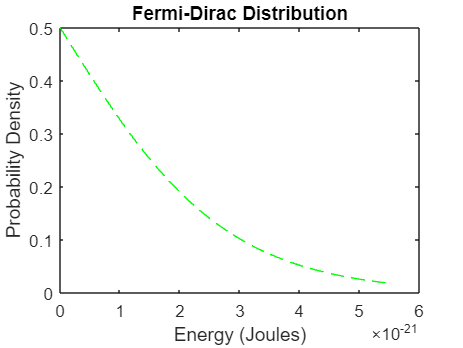

% Fermi-Dirac Distribution
clear all;
T = 100; % Temperature in Kelvin
k = 1.38e-23; % Boltzmann constant

% Energy range
E = linspace(0, 4 * k * T, 1000);

% Fermi-Dirac distribution function
f_FermiDirac = 1 ./ (exp(E / (k * T)) + 1);

% Plotting
figure;
plot(E, f_FermiDirac, 'g--');
xlabel('Energy (Joules)');
ylabel('Probability Density');
title('Fermi-Dirac Distribution');

## Energy distributions for the three cases of a classical gas or a fermionic or bosonic gas

In the code:

The variable x represents the normalized energy (E/kT).

The calculations for bol, be, and fd correspond to the distribution functions for Maxwell-Boltzmann, Bose-Einstein, and Fermi-Dirac, respectively.

%
% Distribution Functions for Maxwell-Boltzmann, Fermi-Dirac and
% Bose-Einstein
%
clear all;              % clears all variables
help Boltz_BE_FD        % Clear the memory and print header

Boltz_BE_FD not found.

    Search the documentation for Boltz_BE_FD



%
fprintf('Energy Distribution Functions for Boltzmann, Fermi-Dirac and Bose-Einstein \n')

Energy Distribution Functions for Boltzmann, Fermi-Dirac and Bose-Einstein 


%
% x = E/kt              % x is a variable that represents energy 
%
x = logspace(-3,1)  

x =     0.0010    0.0012    0.0015    0.0018    0.0021    0.0026    0.0031    0.0037    0.0045    0.0054    0.0066    0.0079    0.0095    0.0115    0.0139    0.0168    0.0202    0.0244    0.0295    0.0356    0.0429    0.0518    0.0625    0.0754    0.0910    0.1099    0.1326    0.1600    0.1931    0.2330    0.2812    0.3393    0.4095    0.4942    0.5964    0.7197    0.8685    1.0481    1.2649    1.5264    1.8421    2.2230    2.6827    3.2375    3.9069    4.7149    5.6899    6.8665    8.2864   10.0000


bol = exp(-x)                          % Maxwell-Boltzmann model

bol =     0.9990    0.9988    0.9985    0.9982    0.9979    0.9974    0.9969    0.9963    0.9955    0.9946    0.9935    0.9921    0.9905    0.9886    0.9862    0.9834    0.9800    0.9759    0.9710    0.9651    0.9580    0.9495    0.9394    0.9273    0.9130    0.8960    0.8758    0.8522    0.8244    0.7922    0.7549    0.7123    0.6640    0.6101    0.5508    0.4869    0.4196    0.3506    0.2823    0.2173    0.1585    0.1083    0.0684    0.0393    0.0201    0.0090    0.0034    0.0010    0.0003    0.0000


be = 1 ./ (exp(x) - 1)                 % Bose-Einstein model

be =   999.5001  828.1429  686.1490  568.4867  470.9868  390.1942  323.2460  267.7699  221.8000  183.7074  152.1423  125.9862  104.3121   86.3521   71.4697   59.1376   48.9188   40.4512   33.4347   27.6207   22.8031   18.8113   15.5038   12.7634   10.4930    8.6121    7.0542    5.7639    4.6956    3.8113    3.0799    2.4753    1.9761    1.5646    1.2262    0.9490    0.7229    0.5399    0.3933    0.2776    0.1883    0.1214    0.0734    0.0409    0.0205    0.0090    0.0034    0.0010    0.0003    0.0000


fd = 1 ./ (exp(x) + 1)       % Fermi-Dirac model

fd =     0.4998    0.4997    0.4996    0.4996    0.4995    0.4994    0.4992    0.4991    0.4989    0.4986    0.4984    0.4980    0.4976    0.4971    0.4965    0.4958    0.4949    0.4939    0.4926    0.4911    0.4893    0.4871    0.4844    0.4812    0.4773    0.4726    0.4669    0.4601    0.4519    0.4420    0.4302    0.4160    0.3990    0.3789    0.3552    0.3275    0.2956    0.2596    0.2201    0.1785    0.1368    0.0977    0.0640    0.0378    0.0197    0.0089    0.0034    0.0010    0.0003    0.0000


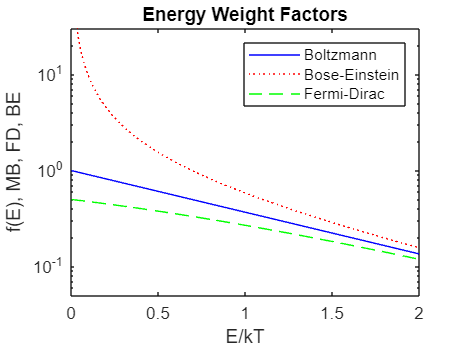

%
figure(1)
semilogy(x,bol,'-b',x, be,':r',x,fd,'g--')
axis([ 0 2 0.05 30])
ylabel('f(E), MB, FD, BE')
xlabel('E/kT')
title('Energy Weight Factors')
legend('Boltzmann','Bose-Einstein','Fermi-Dirac')

%